# Introduction to Simulink

## ================================================

#### Model Construction Basics

This section will show the Library Browser, how to begin to construct simple models, and how to run and save your new model.

- Simulink Start Page

- Library Browser

- Smart Editing Cues

- Connecting Blocks

- Scopes

- Naming blocks/signals

- Running Simulations

Open Simulink.  Note the possible methods for starting Simulink (e.g. menu bar, command window).

simulink

The Simulink Start Page appears.  Briefly demonstrate the benefits of the Start Page (e.g. templates, examples).  Then create a Blank model.

Let's start buliding our model based on first principles, starting with possibly the most obvious force acting on our quadcopter: gravity.  On Earth, gravity exerts a constant force on an object with a corresponding acceleration equal to roughly 9.8 m/s^2.

- We can represent this acceleration using a constant block.  Open the Library Browser and demonstrate how to add blocks to the Simulink canvas by adding a constant block.  Define the constant as `-9.8`.

- We can derive the velocity of the quadcopter by integrating its acceleration.  Drag an Integrator block from the Continuous section onto the canvas (you might consider demonstrating how to search for blocks in the Library Browser) and define the initial condition as `0.5` (this means the quadcopter is initially rising at 0.5 m/s).  Connect the output of the gravity constant to the input of the integrator block.

- We need some way to quickly analyze the results of our quadcopter simulation.  Drag a Scope block onto the canvas and connect it to the output of the integrator block.

- We should now be able to simulate our model to see how the velocity of our quadcopter change under the force gravity.  Let's hits the run button to find out!  After simulation completes, double click the Scope block to see how velocity changes with respect to time.  Is this as you would have expected?

- We can derive position by integrating the velocity.  Add another Integrator block onto the canvas either from the Library Browser, exploiting Quick Insert by type 'Integrator' directly onto the canvas (explain Quick Insert), or select the existing integrator using Ctrl+(left click) and duplicating the block.  Double-click the new integrator and change the initial condition to `1` (the quadcopter is 1 m off the ground).  Connect the input of the new integrator to the output of the first integrator, then connect the output of the second integrator to the scope (consider demonstrating port creation).

- Rerun the simulation and observe the resulting scope plot.  Modify the scope layout to show two separates plots.  Which plot is which?  Add names to the blocks and wires to make the model easier to understand, then rerun and observe the scope plots.  How did the plots change?

The completed model should look something like this...

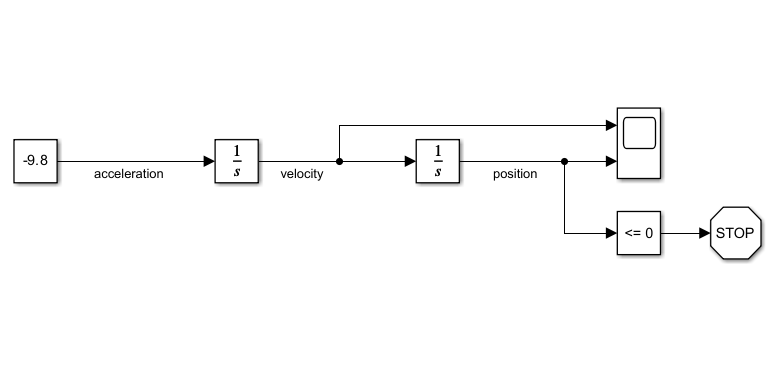

 
open_system('Checkpoint1');

#### Referencing Workspace Data and Comparing Simulations

This section demonstrate the following topics...

- Reference workspace data

- Signal Logging

- Simulink Data Inspector

- Comment out

Now that we've model gravity, we can model the other critical force acting on our quadcopter: lift; however, lift is proportional to our propellers' rotational speed.  Luckily, we have data that captures the relationship between our propeller speed and total lift.  Let's utilize this data for our model...

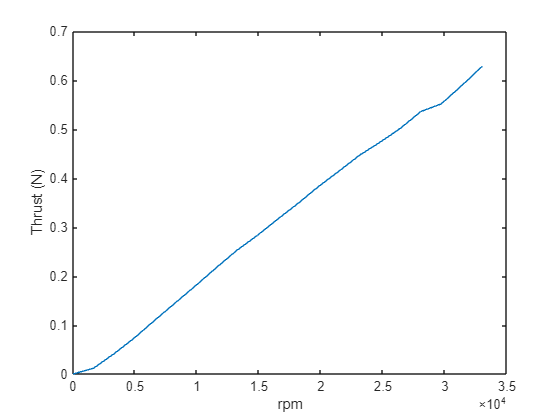

 
% Load prop thrust data into the Base Workspace
load('PROP_DATA_INTRO');

% Plot total prop thrust (N) verse rotational speed (rpm)
plot(PropData.rpm,PropData.liftForce_N);
xlabel 'rpm';
ylabel 'Thrust (N)';

% Clear all previous data from SDI
Simulink.sdi.clear;

- Add a 1-D Lookup Table block

- Within the lookup table's block parameters, enter `PropData.liftForce_N` for Table Data and `PropData.rpm` for Breakpoints 1.  It's worth showing the Lookup Table Editor by selecting 'Edit table and breakpoints...'

- Temporarily add a Constant, define it as 1000, connect it to the lookup table input, and label the signal "rpm"

- Calculate accleration from lift by adding a Divide block, then connect the thrust vector to the first input and a new Constant block (defined as `0.0526`) to the second input of the Divide.  Label the new constant "Mass"

- Sum the acclerations by adding a Sum block (List of signs: `+|+`).  Disconnect the accleration due to gravity from the Integrator and reconnect it to the top Sum input, then connect the accleration due to lift to the bottom input.  Connect the output of the Sum to the Integrator.

- Hit Run.

It's difficult to tell how the addition of lift has affected the behavior of the system based on the Scope plot.  Let's compare before and after the addition of lift using the Simulink Data Inspector...

- Left click on the velocity signal, then left click the three dots that appear to view the available smart editing cues.  Select "Enable Data Logging".  Perform the same action for the position signal.

- Hit Run.  Note that the Simulation Data Inspector icon is highlighted, indicating their is data availabla to plot.

- Open the Simulink Data Inspector by clicking on the SDI icon.  Briefly show some of the features of the SDI

- Plot position and velocity in different plots.

- In the model, select all of the block associated with lift.  Right-click on one of the blocks and select 'Comment Out'.

- Hit Run.  Note that data from the new run is available in the SDI

- Plot position and velocity from the new run against the first run.  Use the Compare feature to show the slight difference between the two runs.

In case anyone is curious, prop hover speed (the speed at which the props generate enough lift to counter the quadcopter's weight) is 27082 rpm.

The completed model should look something like this...

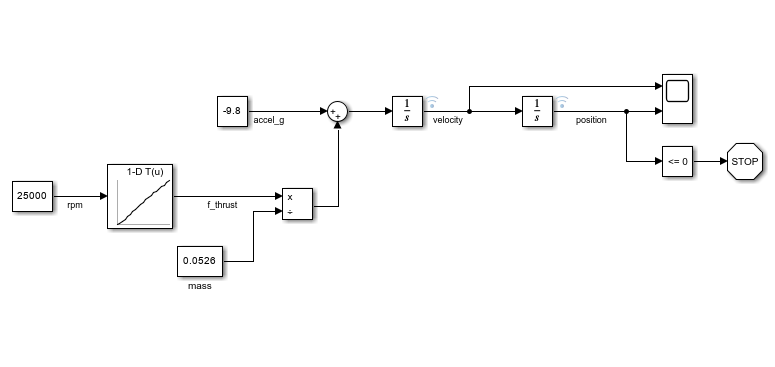

 
open_system('Checkpoint2');

#### Model Hierarchy

This section demonstrates the following topics...

- Creating subsystems

- Simple feedback control

Using first principles, we've developed a simple model that simulates the behavior of our quadcopter, but we want to control this behavior.  This requires closed-loop feedback.  Let's turn our system into a simple control loop.  In the process, we will begin modularizing related object groups using subsystems...

-  Select all objects in the model except the rpm constant and the scope.  Select 'Create Subsystem' from the smart editing cues list.  Label the resulting subsystem "PlantModel".  Briefly describe the concept and benefits of subsystems.

- Redefine the rpm constant block from 1000 to 0 and label the block "v_ref" (representing the desired change in altitutde).

- Add a Sum block (List of signs: `|+-`).  Disconnect the output of the v_ref constant from the subsystem and connect it to the "+" input.  Add a Selector block and use it to connect the third component of the velocity signal to the "-" input of the sum block.

- Add a PID Controller block, connect the output of the sum to the controller, and connect the output of the controller to the input of the subsystem.  Label the input signal "error", and label the output signal "rpm".

- In the controller block parameters, change the controller to PI.  For Automated tuning, ensure 'Transfer Function Based (PID Tuner App)' is selected and open the PID Tuner app by clicking the 'Tune..." button.  In the 'Time' domain, use the 'Response Time (seconds)' and 'Transient Behavior' sliders to adjust controller response.  Hit 'Update Block' when satisfied with the intended response.  Show that the controller parameters were automatically updated.

- Hit Run.  Does the simulation behave as expected?

The completed model should look something like this...

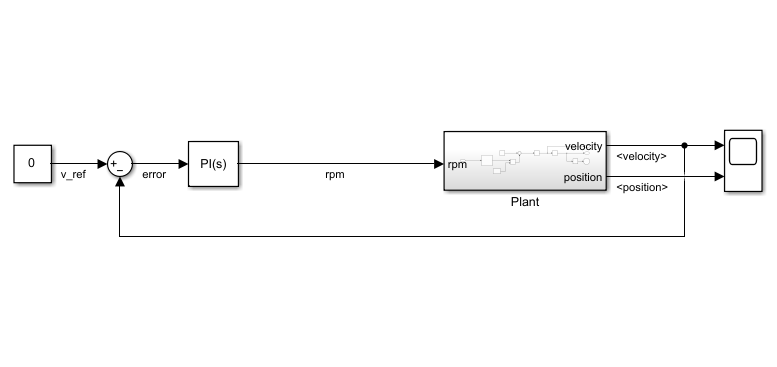

 
open_system('Checkpoint3');

#### Continuous Verse Discrete Sample Rates

This section demonstrates the following topics...

- Continuous vs Discrete time domains

- Sample Time

At the moment our controller is operating in the continuous time domain.  For most controllers this is unrealistic.  To more realistically model the interaction between our controller and the plant model, we need to manage our blocks' sample rates...

- From the menu bar, select Display > Sample Time > Colors.  Briefly describe sample times.

- In the controller block parameters, change Time domain to Discrete-time.

- Perform a diagram update.  Note the PlantModel is now hybrid sample time.

- Redefine PlantModel as continous by inserting Rate Transition blocks before the sum block and after the controller.  Update diagram to demonstrate.

The completed model should look something like this...

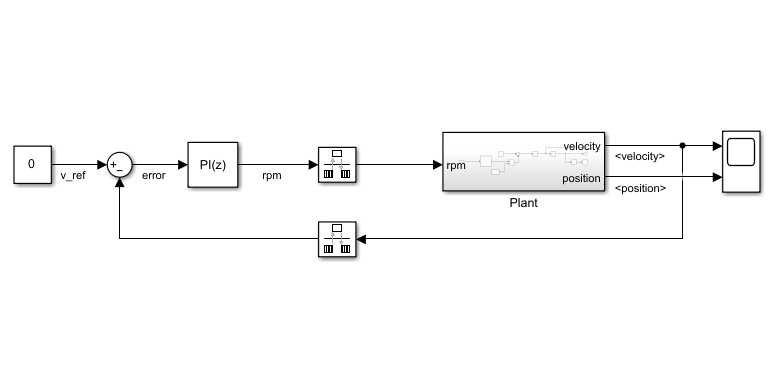

 
open_system('Checkpoint4');

#### Custom Libraries and Model References

- Custom LIbraries

- Masks

- Model References

Let's take a look at slightly more developed model...

 
open_system(new_system('untitledLibrary','Library'));

This model has compartmentalized the blocks associated with system control in the atomic subsystem named FCS.  At this point, you may wish to discuss virtual verse atomic subsystems as they relate to execution order.  Also, note that the velocity and position signals have been gathered into a bus.  You may wish to describe buses and their value with respect to model organization.

Others may want to take advantage of our plant model for their own system.  We can save our plant model off as a block in our own custom library...

- Place a copy of PlantModel into the new library.

- If time permits, right-click on the custom block and select Mask > Create Mask...  Walk through the Mask Editor, including parameterizing the mass using variable `m`.

As the system grows in scope and complexity, it may make sense to break the model up into components that can be worked on separately.  For instance, we may want to develop and test our controller design separate from the rest of the quadcopter.  This can be done using model references...

- If time permits, right-click on FCS subsystem and select 'Subsystem & Model Reference > Convert to > Referenced Model....

- In the Model Reference Conversion Advisor, hit 'Convert' to convert FCS to a model reference.  Briefly describe the concept and value of model references.

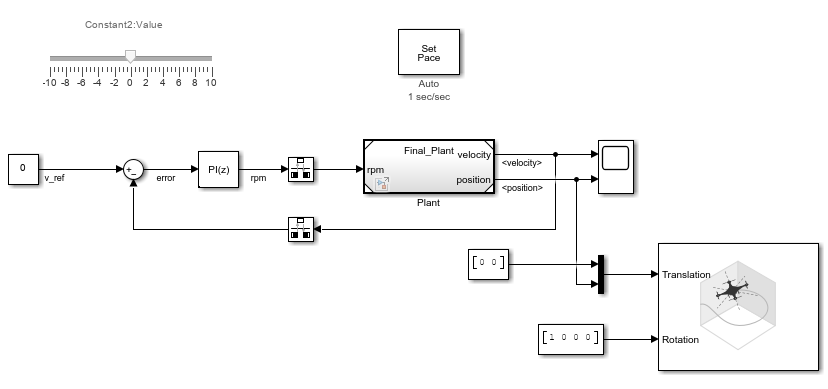

 
open_system('Final_TopModel');

We've successfully modeled the basic concept behind our quadcopter; however, there are still many aspects we need to define within our system model.  The independent lift provided by each propeller and the resulting moments on the quadcopter, the coupling of battery and motor performance, not to mention modeling IMU and onboarding camera data for sensor fusion and control all need to be modeled.  Still, in just a short time we were able to develop the basic architecture of our system and modularize our design for sharing with our team.

Checkpoint 5